close all; clear; clc;

# Test Name

**file name**: CP_vs_CT_plots.mlx

**keywords:** 

**date of test:** date

**file created by:** date, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

P80_2b = xlsread('P80_2b.xlsx');
P80_3b = xlsread('P80_3b.xlsx');
turn = xlsread('Turnigy.xlsx');
mega_2b = xlsread('MEGA_2b.xlsx');
mega_3b = xlsread('MEGA_3b.xlsx');
KDE = xlsread('KDE.xlsx');
mini = xlsread('Mini.xlsx');

## KDE

Q_KDE = KDE(:,10);                          % [ft.lbf]
T_KDE = KDE(:,11);                          % [lbf]
rpm_KDE = KDE(:,14);              % [RPM]
% convert to RPM for plotting purposes
rad_KDE = rpm_KDE .* (pi/30);                       % [rad/sec]
P_out_W_KDE = KDE(:,16);                   % [Watts]
% convert to [ft.lbf/sec]
P_out_KDE = P_out_W_KDE .* 0.7478;                  % [ft.lbf/sec] 
area_KDE = KDE(:,6);
diameter_KDE = KDE(:,5);
p_KDE = KDE(:,24);
st_KDE = KDE(:,22);
dRPM_KDE = KDE(:,27);
mInertia_KDE = KDE(:,1);
rInertia3b_KDE = KDE(:,3);
dP_in_KDE = KDE(:,28);
dP_out_KDE = KDE(:,29);

C_I_KDE = (mInertia_KDE + rInertia3b_KDE) ./ (p_KDE .* area_KDE .* rad_KDE.^3);
C_om_KDE = 1 ./ (st_KDE .* dRPM_KDE);
[CIKDE, COMKDE] = meshgrid(C_I_KDE, C_om_KDE);
C_PI_KDE = CIKDE .* COMKDE;


## MEGA 2b

Q_mega_2b = mega_2b(:,10);                          % [ft.lbf]
T_mega_2b = mega_2b(:,11);                          % [lbf]
rpm_mega_2b = mega_2b(:,14);              % [RPM]
% convert to RPM for plotting purposes
rad_mega_2b = rpm_mega_2b .* (pi/30);                       % [rad/sec]
P_out_W_mega_2b = mega_2b(:,16);                   % [Watts]
% convert to [ft.lbf/sec]
P_out_mega_2b = P_out_W_mega_2b .* 0.7478;                  % [ft.lbf/sec] 
area_mega_2b = mega_2b(:,6);
diameter_mega_2b = mega_2b(:,5);
p_mega_2b = mega_2b(:,24);
st_mega_2b = mega_2b(:,22);
dRPM_mega_2b = mega_2b(:,27);
mInertia_mega_2b = mega_2b(:,1);
%rInertia3b_mega_2b = mega_2b(820:end,3);
%rInertia2b_mega_2b = mega_2b(1:819,3);
rInertia_mega_2b = mega_2b(:,3);
dP_in_mega_2b = mega_2b(:,28);
dP_out_mega_2b = mega_2b(:,29);

C_I_mega_2b = (mInertia_mega_2b + rInertia_mega_2b) ./ (p_mega_2b .* area_mega_2b .* rad_mega_2b.^3);
C_om_mega_2b = 1 ./ (st_mega_2b .* dRPM_mega_2b);
[CIMEGA_2b, COMMEGA_2b] = meshgrid(C_I_mega_2b, C_om_mega_2b);
C_PI_MEGA_2b = CIMEGA_2b .* COMMEGA_2b;


## MEGA 3 blade

Q_mega_3b = mega_3b(:,10);                          % [ft.lbf]
T_mega_3b = mega_3b(:,11);                          % [lbf]
rpm_mega_3b = mega_3b(:,14);              % [RPM]
% convert to RPM for plotting purposes
rad_mega_3b = rpm_mega_3b .* (pi/30);                       % [rad/sec]
P_out_W_mega_3b = mega_3b(:,16);                   % [Watts]
% convert to [ft.lbf/sec]
P_out_mega_3b = P_out_W_mega_3b .* 0.7478;                  % [ft.lbf/sec] 
area_mega_3b = mega_3b(:,6);
diameter_mega_3b = mega_3b(:,5);
p_mega_3b = mega_3b(:,24);
st_mega_3b = mega_3b(:,22);
dRPM_mega_3b = mega_3b(:,27);
mInertia_mega_3b = mega_3b(:,1);
%rInertia3b_mega_3b = mega_3b(820:end,3);
%rInertia2b_mega_3b = mega_3b(1:819,3);
rInertia_mega_3b = mega_3b(:,3);
dP_in_mega_3b = mega_3b(:,28);
dP_out_mega_3b = mega_3b(:,29);

C_I_mega_3b = (mInertia_mega_3b + rInertia_mega_3b) ./ (p_mega_3b .* area_mega_3b .* rad_mega_3b.^3);
C_om_mega_3b = 1 ./ (st_mega_3b .* dRPM_mega_3b);
[CIMEGA_3b, COMMEGA_3b] = meshgrid(C_I_mega_3b, C_om_mega_3b);
C_PI_MEGA_3b = CIMEGA_3b .* COMMEGA_3b;


## Turnigy

Q_turn = turn(:,10);                          % [ft.lbf]
T_turn = turn(:,11);                          % [lbf]
rpm_turn = turn(:,14);              % [RPM]
% convert to RPM for plotting purposes
rad_turn = rpm_turn .* (pi/30);                       % [rad/sec]
P_out_W_turn = turn(:,16);                   % [Watts]
% convert to [ft.lbf/sec]
P_out_turn = P_out_W_turn .* 0.7478;                  % [ft.lbf/sec] 
area_turn = turn(:,6);
diameter_turn = turn(:,5);
p_turn = turn(:,24);
st_turn = turn(:,22);
dRPM_turn = turn(:,27);
mInertia_turn = turn(:,1);
rInertia3b_turn = turn(:,3);
dP_in_turn = turn(:,28);
dP_out_turn = turn(:,29);

C_I_turn = (mInertia_turn + rInertia3b_turn) ./ (p_turn .* area_turn .* rad_turn.^3);
C_om_turn = 1 ./ (st_turn .* dRPM_turn);
[CITURN, COMTURN] = meshgrid(C_I_turn, C_om_turn);
C_PI_TURN = CITURN .* COMTURN;


## P80_2b

Q_P80_2b = P80_2b(:,10);                          % [ft.lbf]
T_P80_2b = P80_2b(:,11);                          % [lbf]
rpm_P80_2b = P80_2b(:,14);              % [RPM]
% convert to RPM for plotting purposes
rad_P80_2b = rpm_P80_2b .* (pi/30);                       % [rad/sec]
P_out_W_P80_2b = P80_2b(:,16);                   % [Watts]
% convert to [ft.lbf/sec]
P_out_P80_2b = P_out_W_P80_2b .* 0.7478;                  % [ft.lbf/sec] 
area_P80_2b = P80_2b(:,6);
diameter_P80_2b = P80_2b(:,5);
p_P80_2b = P80_2b(:,24);
st_P80_2b = P80_2b(:,22);
dRPM_P80_2b = P80_2b(:,27);
mInertia_P80_2b = P80_2b(:,1);
rInertia_P80_2b = P80_2b(:,3);
dP_in_P80_2b = P80_2b(:,28);
dP_out_P80_2b = P80_2b(:,29);

C_I_P80_2b = (mInertia_P80_2b + rInertia_P80_2b) ./ (p_P80_2b .* area_P80_2b .* rad_P80_2b.^3);
C_om_P80_2b = 1 ./ (st_P80_2b .* dRPM_P80_2b);
[CIP80_2b, COMP80_2b] = meshgrid(C_I_P80_2b, C_om_P80_2b);
C_PI_P80_2b = CIP80_2b .* COMP80_2b;


## P80_2b

Q_P80_3b = P80_3b(:,10);                          % [ft.lbf]
T_P80_3b = P80_3b(:,11);                          % [lbf]
rpm_P80_3b = P80_3b(:,14);              % [RPM]
% convert to RPM for plotting purposes
rad_P80_3b = rpm_P80_3b .* (pi/30);                       % [rad/sec]
P_out_W_P80_3b = P80_3b(:,16);                   % [Watts]
% convert to [ft.lbf/sec]
P_out_P80_3b = P_out_W_P80_3b .* 0.7478;                  % [ft.lbf/sec] 
area_P80_3b = P80_3b(:,6);
diameter_P80_3b = P80_3b(:,5);
p_P80_3b = P80_3b(:,24);
st_P80_3b = P80_3b(:,22);
dRPM_P80_3b = P80_3b(:,27);
mInertia_P80_3b = P80_3b(:,1);
rInertia_P80_3b = P80_3b(:,3);
dP_in_P80_3b = P80_3b(:,28);
dP_out_P80_3b = P80_3b(:,29);

C_I_P80_3b = (mInertia_P80_3b + rInertia_P80_3b) ./ (p_P80_3b .* area_P80_3b .* rad_P80_3b.^3);
C_om_P80_3b = 1 ./ (st_P80_3b .* dRPM_P80_3b);
[CIP80_3b, COMP80_3b] = meshgrid(C_I_P80_3b, C_om_P80_3b);
C_PI_P80_3b = CIP80_3b .* COMP80_3b;

%{
C_I_P80_2b = (mInertia_P80 + rInertia2b_P80) ./ (p_P80 .* area_P80 .* rad_P80.^3);
[CIP80_2b, COMP80] = meshgrid(C_I_P80_2b, C_om_P80);
C_PI_KDE = CIP80_2b .* COMP80;
%}


## Mini

Q_mini = mini(:,10);                          % [ft.lbf]
T_mini = mini(:,11);                          % [lbf]
rpm_mini = mini(:,14);              % [RPM]
% convert to RPM for plotting purposes
rad_mini = rpm_mini .* (pi/30);                       % [rad/sec]
P_out_W_mini = mini(:,16);                   % [Watts]
% convert to [ft.lbf/sec]
P_out_mini = P_out_W_mini .* 0.7478;                  % [ft.lbf/sec] 
area_mini = mini(:,6);
diameter_mini = mini(:,5);
p_mini = mini(:,24);
st_mini = mini(:,22);
dRPM_mini = mini(:,27);
mInertia_mini = mini(:,1);
rInertia_mini = mini(:,3);
dP_in_mini = mini(:,28);
dP_out_mini = mini(:,29);

C_I_mini = (mInertia_mini + rInertia_mini) ./ (p_mini .* area_mini .* rad_mini.^3);
C_om_mini = 1 ./ (st_mini .* dRPM_mini);
[CIMINI, COMMINI] = meshgrid(C_I_mini, C_om_mini);
C_PI_MINI = CIMINI .* COMMINI;


## Plots

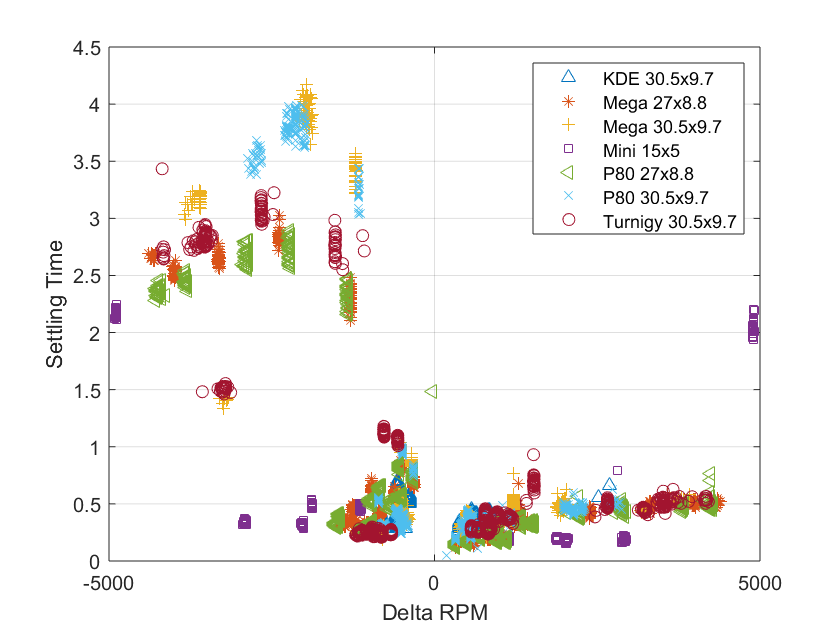

figure(1)
plot(dRPM_KDE, st_KDE, '^', ...
    dRPM_mega_2b, st_mega_2b, '*', dRPM_mega_3b, st_mega_3b, '+',...
    dRPM_mini, st_mini, 's', ...
    dRPM_P80_2b, st_P80_2b, '<', dRPM_P80_3b, st_P80_3b, 'x', ...
    dRPM_turn, st_turn, 'o'); grid on;
xlim([-5000 5000]);
legend('KDE 30.5x9.7', 'Mega 27x8.8', 'Mega 30.5x9.7',...
    'Mini 15x5', 'P80 27x8.8',...
    'P80 30.5x9.7', 'Turnigy 30.5x9.7');
xlabel('Delta RPM'); ylabel('Settling Time'); 

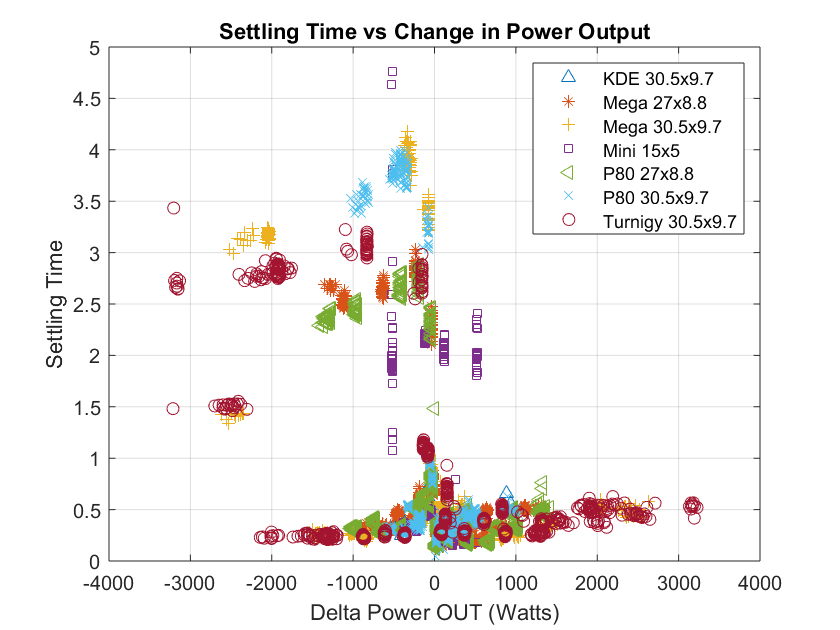

%title('Settling Time vs Change in RPM');

figure(2)
plot(dP_out_KDE, st_KDE, '^',...
    dP_out_mega_2b, st_mega_2b, '*', dP_out_mega_3b, st_mega_3b, '+',...
    dP_out_mini, st_mini, 's', ...
    dP_out_P80_2b, st_P80_2b, '<', dP_out_P80_3b, st_P80_3b, 'x', ...
    dP_out_turn, st_turn, 'o');
grid 'on';
xticks(-5000:1000:5000);
yticks(0:0.5:5);
legend('KDE 30.5x9.7', 'Mega 27x8.8', 'Mega 30.5x9.7',...
    'Mini 15x5', 'P80 27x8.8',...
    'P80 30.5x9.7', 'Turnigy 30.5x9.7');
xlabel('Delta Power OUT (Watts)'); ylabel('Settling Time');
title('Settling Time vs Change in Power Output');

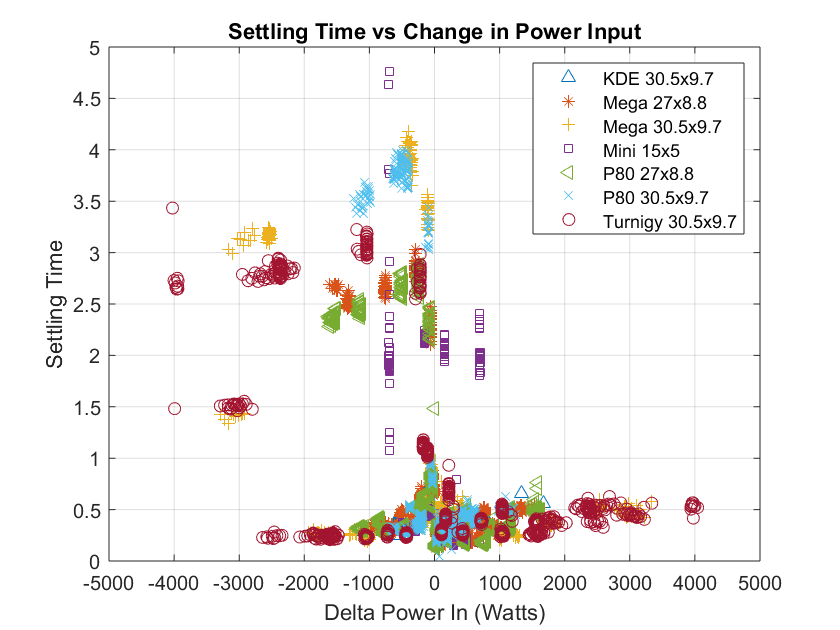


figure(5)
plot(dP_in_KDE, st_KDE, '^',...
    dP_in_mega_2b, st_mega_2b, '*', dP_in_mega_3b, st_mega_3b, '+',...
    dP_in_mini, st_mini, 's', ...
    dP_in_P80_2b, st_P80_2b, '<', dP_in_P80_3b, st_P80_3b, 'x', ...
    dP_in_turn, st_turn, 'o');
grid 'on';
xticks(-5000:1000:5000);
yticks(0:0.5:5);
legend('KDE 30.5x9.7', 'Mega 27x8.8', 'Mega 30.5x9.7',...
    'Mini 15x5', 'P80 27x8.8',...
    'P80 30.5x9.7', 'Turnigy 30.5x9.7');
xlabel('Delta Power In (Watts)'); ylabel('Settling Time');
title('Settling Time vs Change in Power Input');

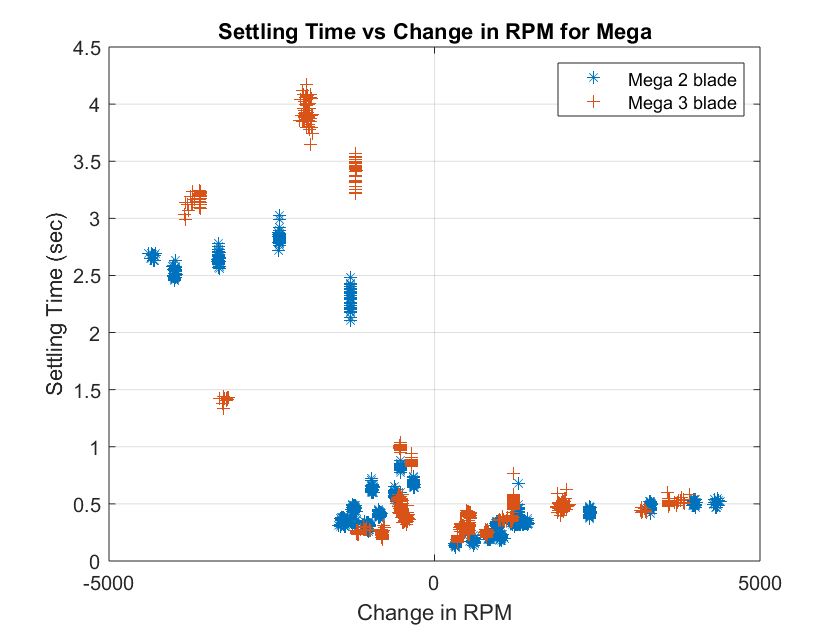


figure(3)
plot(dRPM_mega_2b, st_mega_2b, '*', dRPM_mega_3b, st_mega_3b, '+');
legend('Mega 2 blade', 'Mega 3 blade');
xlabel('Change in RPM'); ylabel('Settling Time (sec)');
title('Settling Time vs Change in RPM for Mega');
grid on;

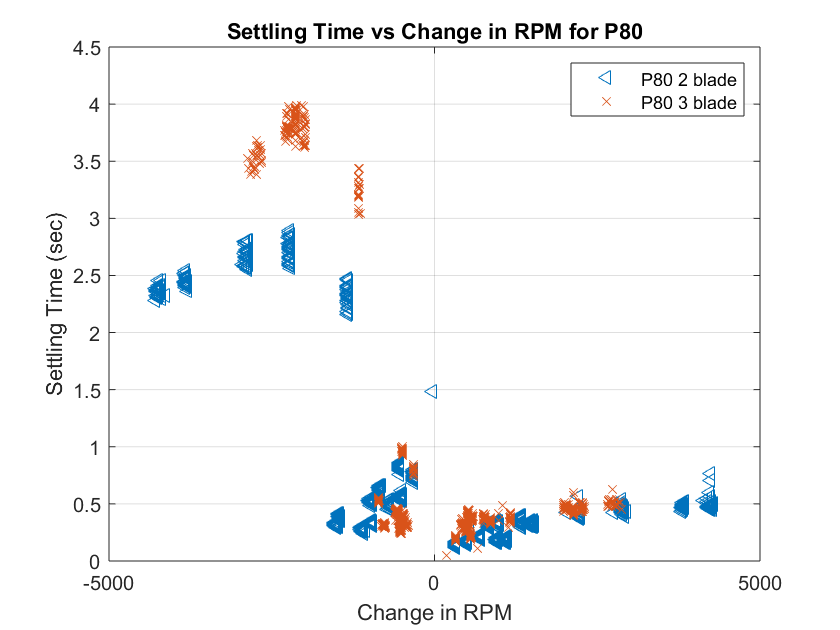


figure(4)
plot(dRPM_P80_2b, st_P80_2b, '<', dRPM_P80_3b, st_P80_3b, 'x' );
legend('P80 2 blade', 'P80 3 blade');
xlabel('Change in RPM'); ylabel('Settling Time (sec)');
title('Settling Time vs Change in RPM for P80');
ylim([0 4.5]);
grid on;

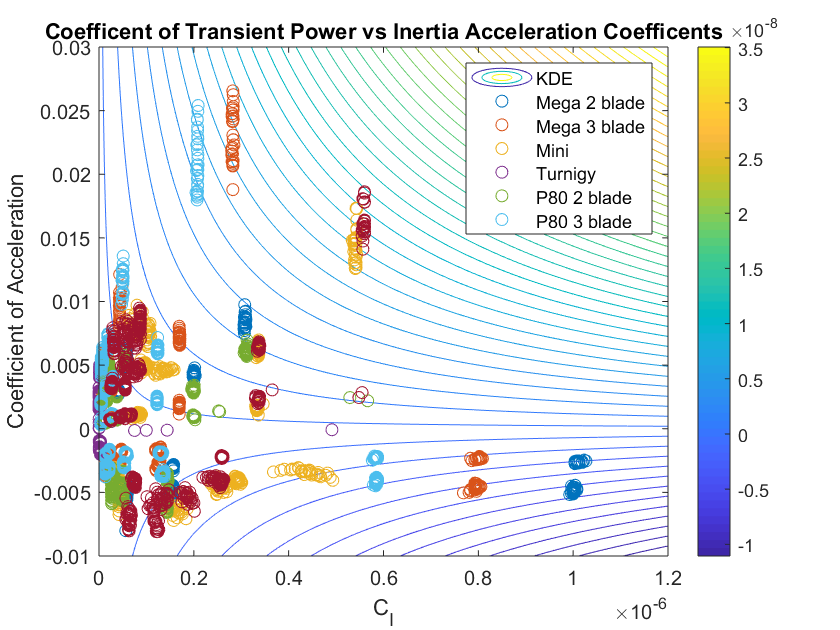

x = linspace(0, 1.2e-6, 1000 );
y = linspace(-0.01, 0.03, 1000);
[X, Y] = meshgrid(x,y);
Z = X .* Y;

figure(5)
contour(X, Y, Z, 50, 'ShowText', 'off');
hold on
plot(C_I_KDE, C_om_KDE, 'o',...
    C_I_mega_2b, C_om_mega_2b, 'o', C_I_mega_3b, C_om_mega_3b, 'o',...
    C_I_mini, C_om_mini, 'o', C_I_turn, C_om_turn, 'o',...
    C_I_P80_2b, C_om_P80_2b, 'o', C_I_P80_3b, C_om_P80_3b, 'o');
ylabel('Coefficient of Acceleration'); xlabel('C_I'); 
xlim([0 1.2e-6]);
legend('KDE','Mega 2 blade', 'Mega 3 blade','Mini', 'Turnigy', 'P80 2 blade', 'P80 3 blade' );
title('Coefficent of Transient Power vs Inertia Acceleration Coefficents')
colorbar

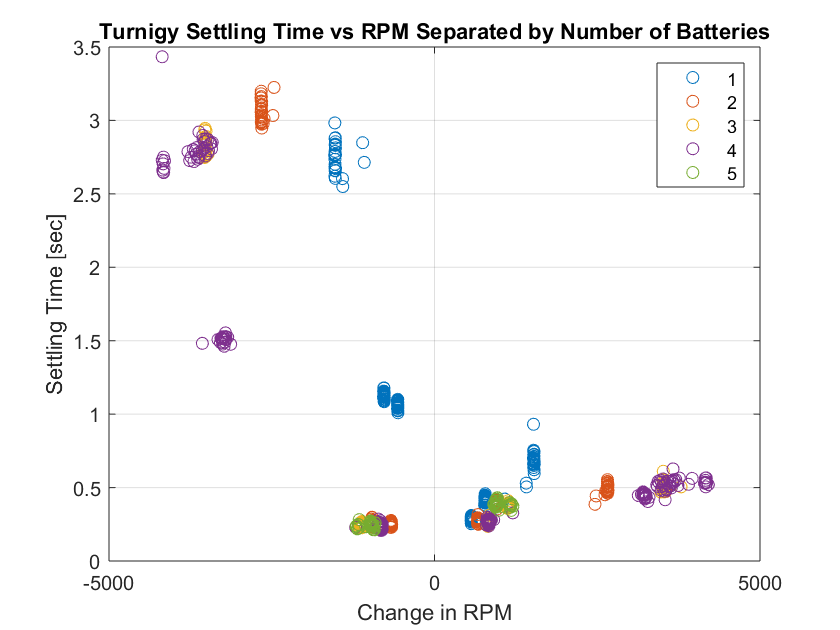



figure(6)
plot(dRPM_turn(1:180), st_turn(1:180), 'o',...
    dRPM_turn(181:361), st_turn(181:361), 'o',...
    dRPM_turn(362:541), st_turn(362:541), 'o',...
    dRPM_turn(542:722), st_turn(542:722), 'o',...
    dRPM_turn(723:end), st_turn(723:end), 'o');
legend('1', '2', '3', '4', '5');
grid on; title('Turnigy Settling Time vs RPM Separated by Number of Batteries');
xlabel('Change in RPM'); ylabel('Settling Time [sec]');

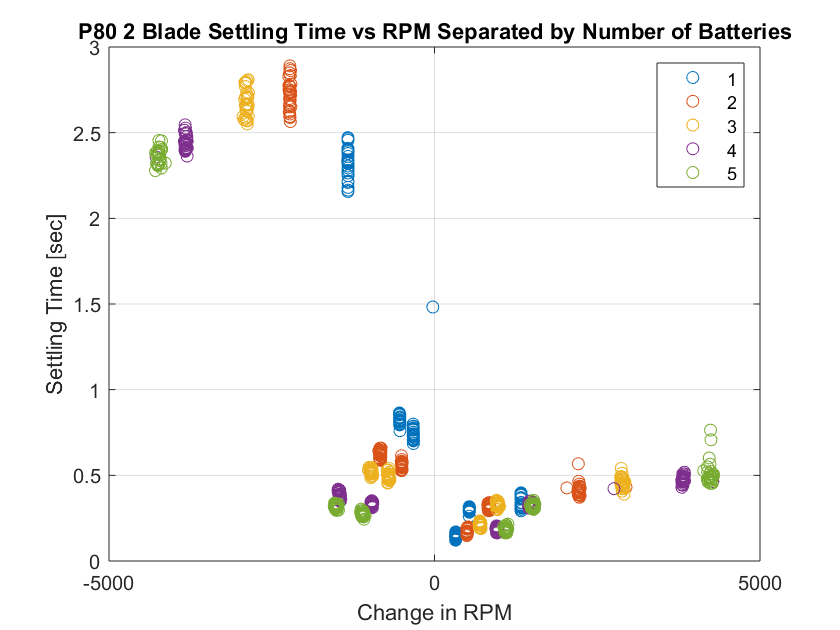




figure(7)
plot(dRPM_P80_2b(1:180), st_P80_2b(1:180), 'o',...
    dRPM_P80_2b(181:361), st_P80_2b(181:361), 'o',...
    dRPM_P80_2b(362:541), st_P80_2b(362:541), 'o',...
    dRPM_P80_2b(542:722), st_P80_2b(542:722), 'o',...
    dRPM_P80_2b(723:end), st_P80_2b(723:end), 'o');
legend('1', '2', '3', '4', '5');
grid on; title('P80 2 Blade Settling Time vs RPM Separated by Number of Batteries');
xlabel('Change in RPM'); ylabel('Settling Time [sec]');

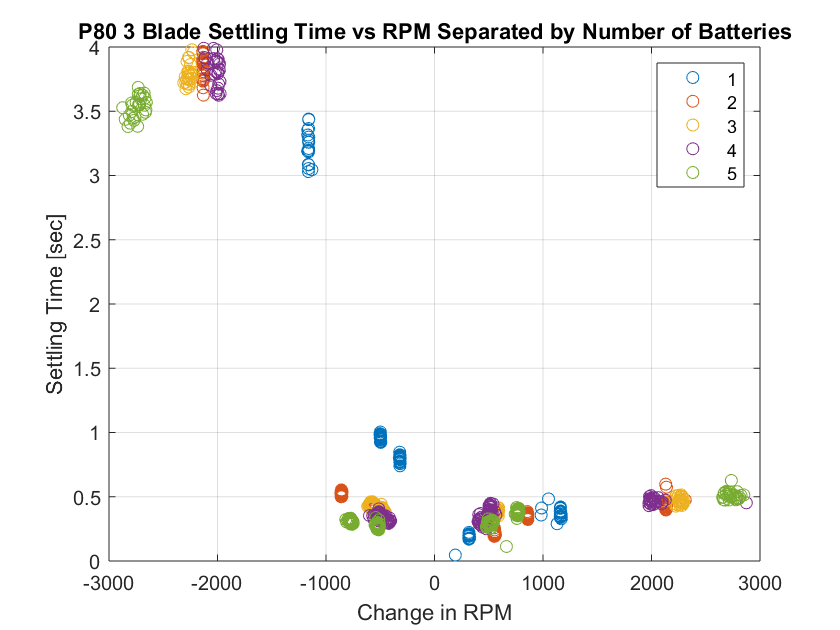



figure(8)
plot(dRPM_P80_3b(1:158), st_P80_3b(1:158), 'o',...
    dRPM_P80_3b(159:337), st_P80_3b(159:337), 'o',...
    dRPM_P80_3b(338:511), st_P80_3b(338:511), 'o',...
    dRPM_P80_3b(512:689), st_P80_3b(512:689), 'o',...
    dRPM_P80_3b(690:end), st_P80_3b(690:end), 'o');
legend('1', '2', '3', '4', '5');
grid on; title('P80 3 Blade Settling Time vs RPM Separated by Number of Batteries');
xlabel('Change in RPM'); ylabel('Settling Time [sec]');

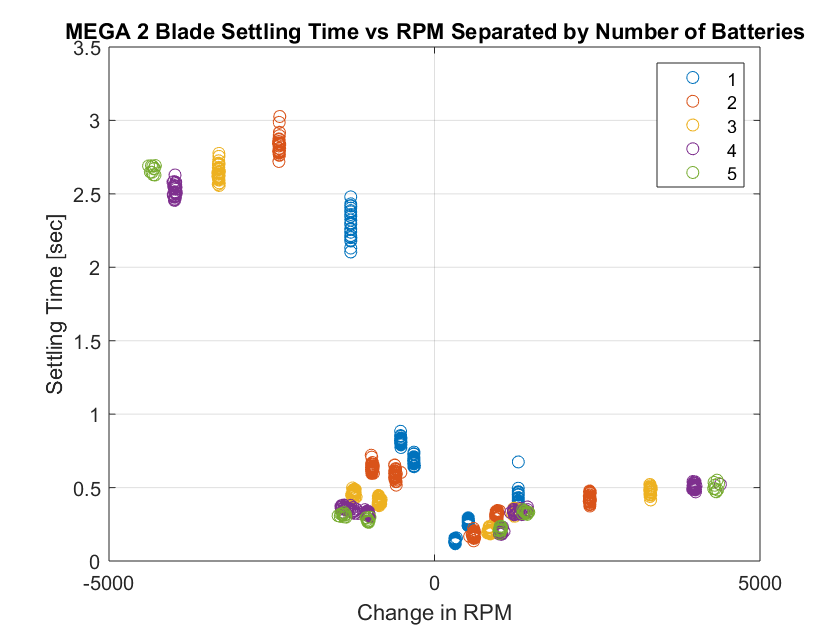


figure(9)
plot(dRPM_mega_2b(1:180), st_mega_2b(1:180), 'o',...
    dRPM_mega_2b(181:361), st_mega_2b(181:361), 'o',...
    dRPM_mega_2b(362:540), st_mega_2b(362:540), 'o',...
    dRPM_mega_2b(541:721), st_mega_2b(541:721), 'o',...
    dRPM_mega_2b(722:end), st_mega_2b(722:end), 'o');
legend('1', '2', '3', '4', '5');
grid on; title('MEGA 2 Blade Settling Time vs RPM Separated by Number of Batteries');
xlabel('Change in RPM'); ylabel('Settling Time [sec]');

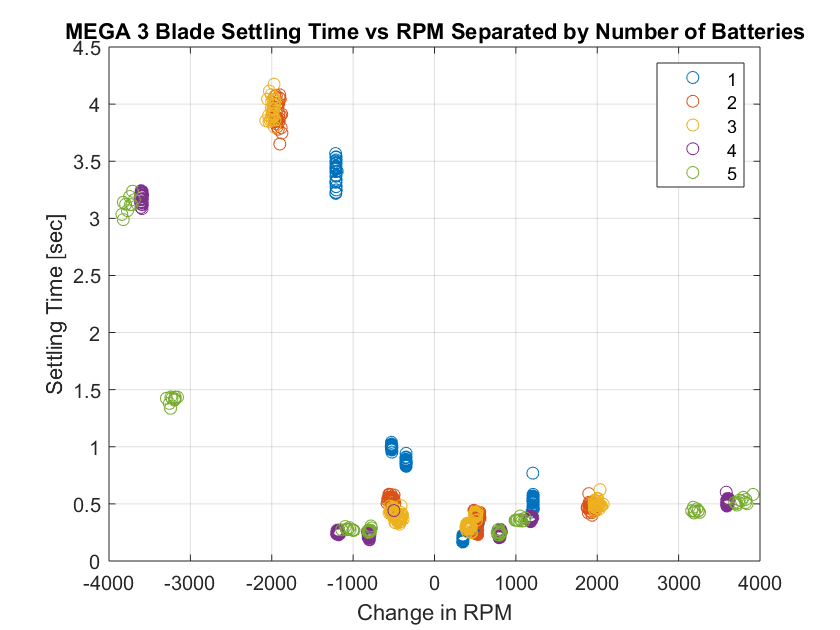




figure(10)
plot(dRPM_mega_3b(1:180), st_mega_3b(1:180), 'o',...
    dRPM_mega_3b(181:360), st_mega_3b(181:360), 'o',...
    dRPM_mega_3b(361:540), st_mega_3b(361:540), 'o',...
    dRPM_mega_3b(540:720), st_mega_3b(540:720), 'o',...
    dRPM_mega_3b(721:end), st_mega_3b(721:end), 'o');
legend('1', '2', '3', '4', '5');
grid on; title('MEGA 3 Blade Settling Time vs RPM Separated by Number of Batteries');
xlabel('Change in RPM'); ylabel('Settling Time [sec]');

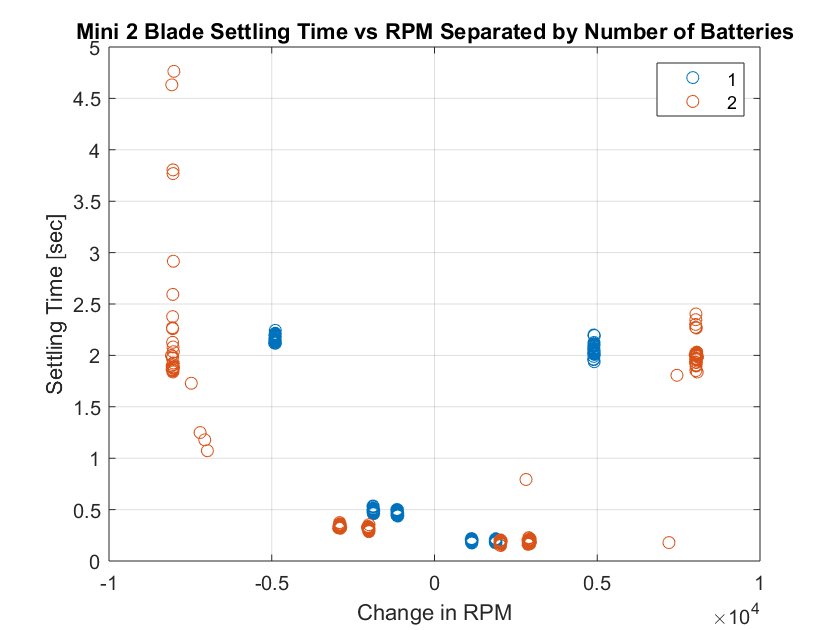



figure(11)
plot(dRPM_mini(1:180), st_mini(1:180), 'o',...
    dRPM_mini(181:360), st_mini(181:360), 'o');
legend('1', '2');
grid on; title('Mini 2 Blade Settling Time vs RPM Separated by Number of Batteries');
xlabel('Change in RPM'); ylabel('Settling Time [sec]');

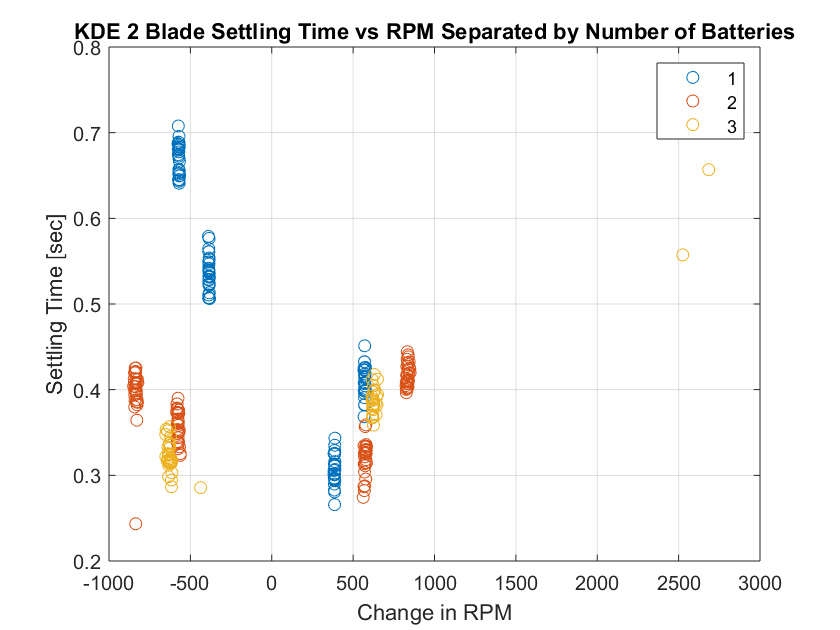



figure(12)
plot(dRPM_KDE(1:120), st_KDE(1:120), 'o',...
    dRPM_KDE(121:240), st_KDE(121:240), 'o',...
    dRPM_KDE(241:end), st_KDE(241:end), 'o');
legend('1', '2', '3');
grid on; title('KDE 2 Blade Settling Time vs RPM Separated by Number of Batteries');
xlabel('Change in RPM'); ylabel('Settling Time [sec]');